open_system("Articulated_arm_real_proportions");

test

path_simu = 'Articulated_arm_real_proportions';

set_param(path_simu, 'SolverType', 'Fixed-step');   % fixed-step solver
%before : set_param(path_simu, 'FixedStep', '0.001');         % time step in sec
set_param(path_simu, 'FixedStep', '0.001'); 
%before set_param(path_simu, 'StopTime', '100'); 
set_param(path_simu, 'StopTime', '250');             % simulate time

Sweep Value

K1 = 0.08;
K2 = 0.4;
K3 = 0.4;
delta_theta = 0.5;


L1 = 0.145;
L2 = 0.2359;
L3 = 0.4191;
small_seg = -0.0275;


set_param(path_simu, 'FastRestart', 'off');

set_param([path_simu '/Gain3'],  'Gain', num2str(K1));
set_param([path_simu '/Gain9'],  'Gain', num2str(K1));
set_param([path_simu '/Gain4'],  'Gain', num2str(K2));
set_param([path_simu '/Gain10'], 'Gain', num2str(K2));
set_param([path_simu '/Gain5'],  'Gain', num2str(K3));
set_param([path_simu '/Gain8'],  'Gain', num2str(K3));
set_param([path_simu '/delta_angle_deg_const'], 'Value', num2str(delta_theta));

simOut = sim(path_simu);

-------------------------
end = -0.039662
end = 0.000000
end = 0.275693
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.049480
end = 0.000000
end = 0.283433
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.050046
end = 0.000000
end = 0.283841
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.060497
end = 0.000000
end = 0.291227
-------------------------
best_next_thet

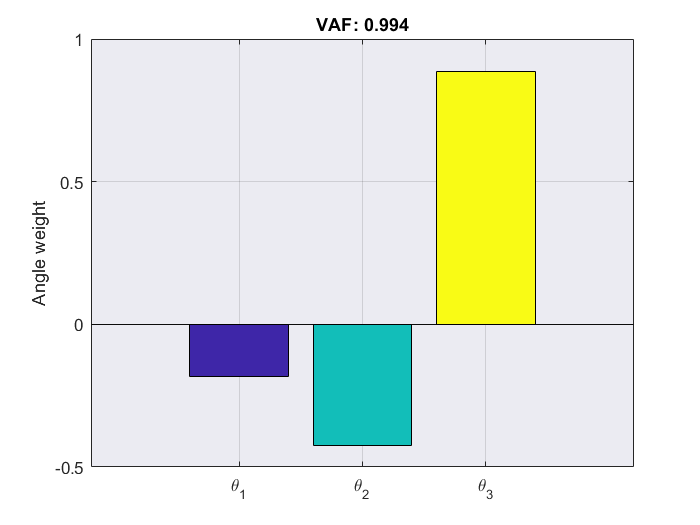


logsout = simOut.logsout;

t = logsout.getElement('theta_1').Values.Time;

theta_1_signal = logsout.getElement('theta_1');
theta_2_signal = logsout.getElement('theta_2');
theta_3_signal = logsout.getElement('theta_3');

theta_1_array_prev = squeeze(theta_1_signal.Values.Data);
theta_2_array_prev = squeeze(theta_2_signal.Values.Data);
theta_3_array_prev = squeeze(theta_3_signal.Values.Data);


theta_1_array = theta_1_array_prev(:,1);
theta_2_array = theta_2_array_prev(:,1);
theta_3_array = theta_3_array_prev(:,1);


Theta = [theta_1_array, theta_2_array, theta_3_array];


[coeff, ~, ~, ~, explained] = pca(Theta);

nComp = size(coeff, 2);   % = 3



% Figure 1: one synergy as a vector of angle weights (like the slide)
synergyIdx = 1;                       
w = coeff(:, synergyIdx);             
vaf = explained(synergyIdx) / 100;

fig1 = figure;
b = bar(w, 'FaceColor', 'flat');

cmap = parula(nComp);
for k = 1:nComp
    b.CData(k,:) = cmap(k,:);
end

set(gca, 'XTickLabel', {'\theta_1','\theta_2','\theta_3'});
ylabel('Angle weight');
title(sprintf('VAF: %.3f', vaf));
yline(0, 'k-');                       
grid on;
set(gca, 'Color', [0.92 0.92 0.95]); 
% Figure 2: cumulative variance explained
fig2 = figure;
cumExplained = cumsum(explained) / 100;      % convert % -> fraction (0..1)
plot(1:nComp, cumExplained, '-', 'LineWidth', 2, 'Color', [0.27 0.45 0.77]);
xlabel('PC');
ylabel('Cummulative Variance');
ylim([0 1]);
xlim([1 nComp]);
xticks(1:nComp);
grid on;


%name figures
paramTag = sprintf('K1_%g_K2_%g_K3_%g_dth_%g', K1, K2, K3, delta_theta);
paramTag = strrep(paramTag, '.', 'p');

baseName = [matlab.lang.makeValidName(method_name) '_' paramTag];

% save figures
fig1_name = [baseName '_bar_graph.png'];
exportgraphics(fig1, fig1_name, 'Resolution', 300);

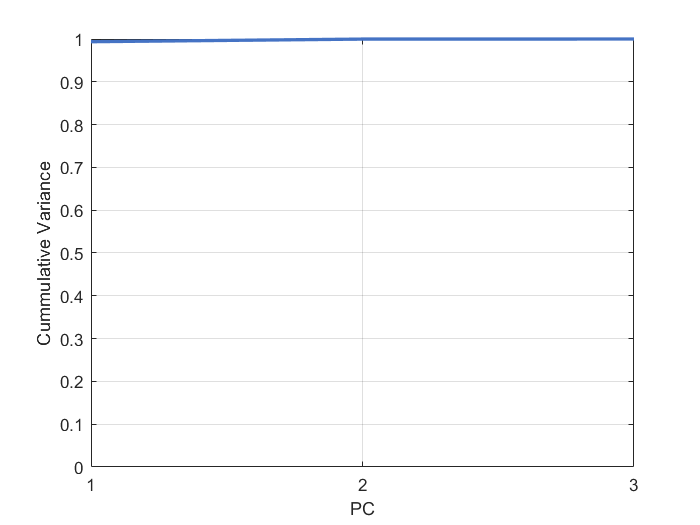


fig2_name = [baseName '_cumulative.png'];
exportgraphics(fig2, fig2_name, 'Resolution', 300);


disp(['Saved: ' fig1_name]);

Saved: BasicCostFunction_K1_0p08_K2_0p4_K3_0p4_dth_0p5_bar_graph.png


disp(['Saved: ' fig2_name]);

Saved: BasicCostFunction_K1_0p08_K2_0p4_K3_0p4_dth_0p5_cumulative.png
